## 1. feladat

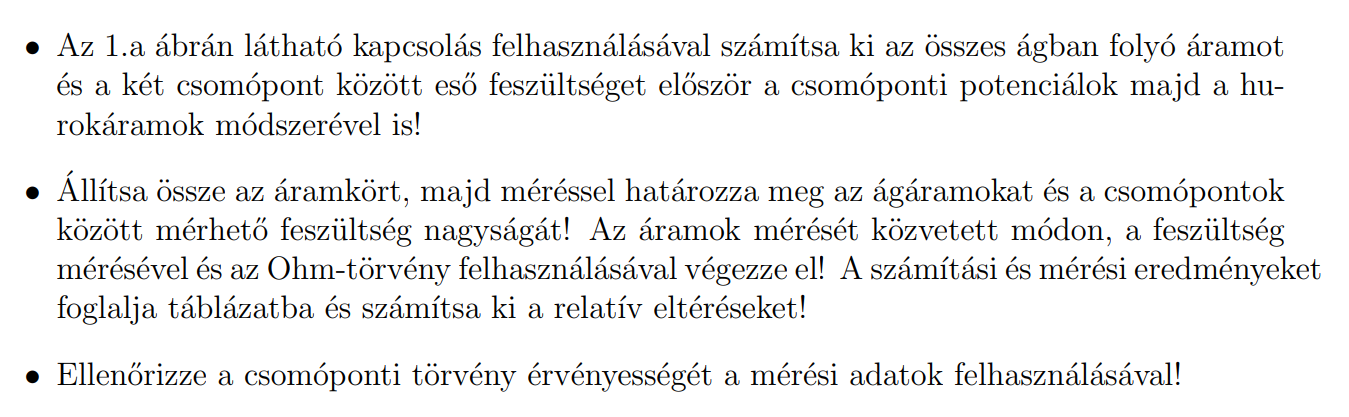

[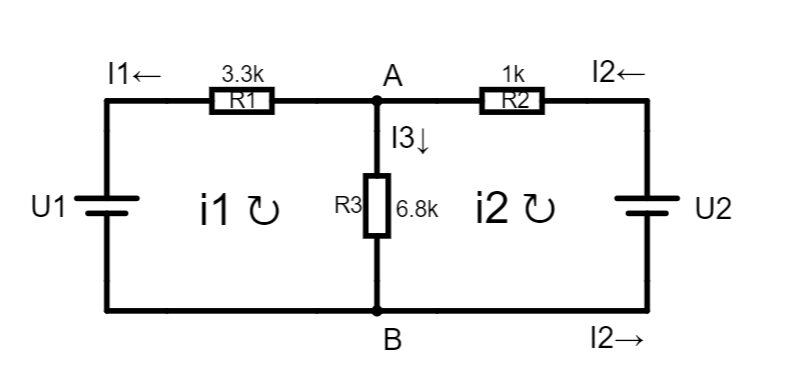](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnKFNAkAmsl7dc+SGwDu-QcNZoefcVLkKUQlGAhK18oX2SbV4rgYh6QaNGeGD4ki1dVoExI-Zl8muXTc46NZuqWWiDEAtoqwf5WNBFBYDQCFglQ9pEppsmxaYYxFi5ZqVLOrnklDlr25ebVhtpePp7eAUXShTR52h0pDe32vXkDjuIAbiBDEL2ZseA09DMwCGxj5VG1ITQprgvQSwAeIKIozWD6uEjWIABK7AfIWGe6pPTI5+A812hsBwSkKAT6SBmUjId7qK64b7jPAoUg0JgIF7PMGuACqtwsBFByBBh0g2NIEDMaK+d2QSCEMgpaHoxJAAEEoawkCRsc4LMQiShXAAhKFTHHjF6WFEgACSyEACYRQyyuVh8ZzU0F0sVoaVkv7kl4ZAoq3CAZMIZeySB0EBASLTueK0IAkwiZlBxEGIBMo5ogAEtkAAdADOgG7CJmc2H0DD6UiuN0gd1oX0BoA)

### Adatok

U_1 = 3;
U_2 = 6;
R_1 = 3300;
R_2 = 1000;
R_3 = 6800;

### Képletek

$I=\frac{U}{R}$Ohm törvénye

$0=I_1 \pm I_2 +\ldotp \ldotp +I_n$ Kirchhoff csomóponti törvényének formalizált alakja

$V_a -V_b =U_{\textrm{g1}} \pm U_{\textrm{g2}} \pm \ldotp \ldotp \pm U_{\textrm{gn}} \pm I_1 \cdot R_1 \pm \ldotp \ldotp \pm I_n \cdot R_n$ Kirchhoff hurok törvényének formalizált alakja

### Csomóponti

#### Számolás

Első lépés, hogy felírjuk a csomópontokra a csomóponti törvényt. $I_2 =I_1 +I_3$ ($A$ és $B$ pont is azonos)

$V_a -V_b =R_1 \cdot I_1 +U_1$ (balra)

$V_a -V_b =-R_2 \cdot I_2 +U_2$ (jobbra)

$V_a -V_b =R_3 \cdot I_3$(lefele)

Fejezzük ki az I-ket úgy, hogy feltételezzük, hogy $V_b =\emptyset$

$I_1 =\frac{V_a -U_1 }{R_1 }$,$I_2 =-\frac{V_a -U_2 }{R_2 }$,$I_3 =\frac{V_a }{R_3 }$

Csomópontiba behelyettesítünk


$$\begin{array}{l}
\frac{V_a -U_1 }{R_1 }+\frac{V_a }{R_3 }+\frac{V_a -U_2 }{R_2 }=0\\
\frac{V_a }{R_1 }-\frac{U_1 }{R_1 }+\frac{V_a }{R_3 }-\frac{U_2 }{R_2 }+\frac{V_a }{R_2 }=0\\
V_a \left(\frac{1}{R_1 }+\frac{1}{R_3 }+\frac{1}{R_2 }\right)=\frac{U_2 }{R_2 }+\frac{U_1 }{R_1 }\\
V_a =\frac{\frac{U_2 }{R_2 }+\frac{U_1 }{R_1 }}{\frac{1}{R_1 }+\frac{1}{R_3 }+\frac{1}{R_2 }}
\end{array}$$


V_a = ((U_2 / R_2) + (U_1 / R_1)) / ((1/R_1)+(1/R_3)+(1/R_2))

V_a = 4.7646

I_1 = (V_a - U_1) / R_1

I_1 = 5.3473e-04

I_2 = - (V_a - U_2) / R_2

I_2 = 0.0012

I_3 = V_a / R_3

I_3 = 7.0068e-04


$$V_a -V_b =4,76V$$



$$I_1 =0,534\mathrm{mA},I_2 =1,2\mathrm{mA},I_3 =0,7\mathrm{mA}$$


#### Ellenőrzés

[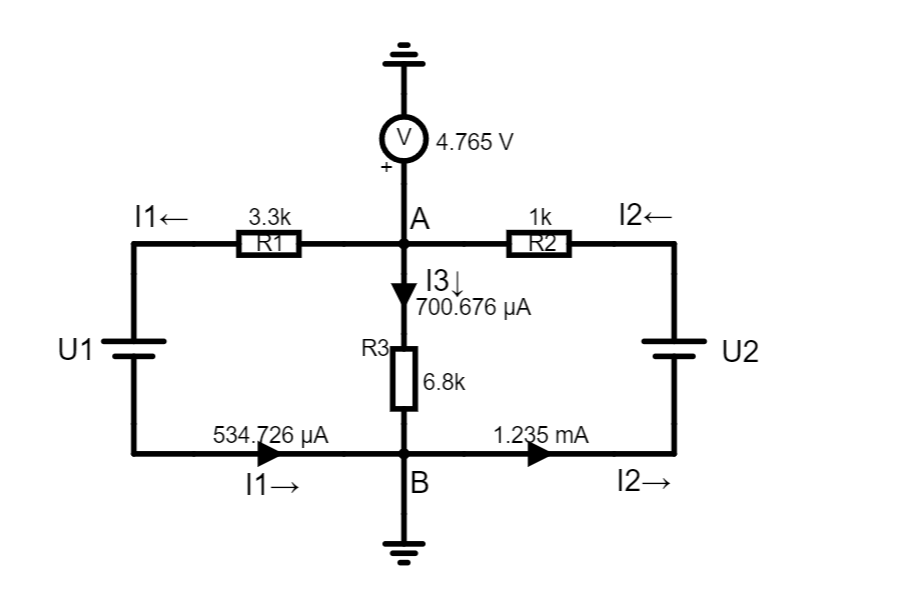](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgAnKcFPEPKmF7dsuSGwDu-QcNYoefcVLkLwQ8DRpRJa+UL5hNq8V0Nb9IFCnPDB8HVZt8UCQsZ0y+TbHtudd4BhuKo7chAJKAaEhNFSRMVQClrHayurWgkYZqZauyVQubqGRhaqlZjnevl4+GlqRBSlV+ZW12c3FbABuIB3WvbUVcbRU9MMwCN25Rf3lRsMpbuPQkwAeIKLgtTQG2Eg2IABK7OtgGLt6xPRge7Q8Ryhs63jE4HgGkObEEAeH2E+9HDgYhUJgIa5XO5gNwAVROljwEDA3w2kCRxC05lhj1OYCQQhk+JQ9CxIAAggDWEgiEiXJZCJjwG4AEIA5qsV7eHjyUkASTAgATCAFWYJgZwIIk-JkgXkoIWnYngcF1JVuPnYQDJhMK6UQCggtEQSdLZYAkwjYAHMohg9Ol3tx4ulrVEUg75MRRdVtAAHALugI7Db2i3+gzqWpxNjYDDDbJJbIQCPrTD0+R5Ij7Y1gM1SUrZULZcRRzIGlL5lIJ7RFgIVFRnYJBoA)

### Hurokáramok


$$\begin{array}{l}
I_1 =-i_1 \\
I_2 =-i_2 \\
I_3 =i_1 -i_2 
\end{array}$$


$\begin{array}{l}
U_1 +R_1 \cdot i_1 -R_3 \cdot \left(i_1 -i_2 \right)=0\\
U_2 +R_2 \cdot i_2 -R_3 \cdot \left(i_1 -i_2 \right)=0
\end{array}$  elsőből kifejezés $\begin{array}{l}
R_1 \cdot i_1 -R_3 \cdot \left(i_1 -i_2 \right)=-U_1 \\
R_1 \cdot i_1 -R_3 i_1 +R_3 i_2 =-U_1 \\
i_1 \left(R_1 -R_3 \right)=-U_1 -R_3 i_2 \\
i_1 =\frac{-U_1 -R_3 i_2 }{R_1 -R_3 }
\end{array}$ 


$$\begin{array}{l}
U_2 +R_2 \cdot i_2 -R_3 \cdot \left(\frac{-U_1 -R_3 i_2 }{R_1 -R_3 }-i_2 \right)=0\\
R_2 \cdot i_2 -R_3 \cdot \frac{-U_1 -R_3 i_2 }{R_1 -R_3 }+R_3 \cdot i_2 =-U_2 \\
R_2 \cdot i_2 +\frac{U_1 R_3 +R_3 R_3 i_2 }{R_1 -R_3 }+R_3 \cdot i_2 =-U_2 \\
R_2 \cdot i_2 +\frac{U_1 R_3 }{R_1 -R_3 }+\frac{R_3 R_3 i_2 }{R_1 -R_3 }+R_3 \cdot i_2 =-U_2 \\
R_2 \cdot i_2 +\frac{R_3 R_3 i_2 }{R_1 -R_3 }+R_3 \cdot i_2 =-U_2 -\frac{U_1 R_3 }{R_1 -R_3 }\\
i_2 \left(R_2 +\frac{R_3 R_3 }{R_1 -R_3 }+R_3 \right)=-U_2 -\frac{U_1 R_3 }{R_1 -R_3 }\\
i_2 =-\frac{U_2 +\frac{U_1 R_3 }{R_1 -R_3 }}{R_2 +\frac{R_3 R_3 }{R_1 -R_3 }+R_3 }\\
i_2 =-\frac{U_2 +\frac{U_1 R_3 }{R_1 -R_3 }}{R_2 +R_3 \left(\frac{R_3 }{R_1 -R_3 }+1\right)}
\end{array}$$


i_2 = -(U_2 + (U_1*R_3) / (R_1 - R_3)) / (R_2 + R_3 * ( (R_3 / (R_1 - R_3)) + 1))

i_2 = 3.1679e-05

i_1 = (-U_1 - R_3 * i_2) / (R_1-R_3)

i_1 = 9.1869e-04